# Radar Array Optimization 

Written by team ArrAnt

University of Colorado Colorado Springs

Members:

-  Cynthia Valentine

-  Joseph Russ

-  Brianna McCague

-  Brett Ford

For and under the guidance of Northrop Grumman

## Input Parameters

Parameters inputed in the live script will be used in the radar_optimization script to create the population of pareto optimal solutions for radar arrays. 

 k= 0.6; % efficiency of antenna
 nu = 3;  % frequency (GHz) which is converted to meters for the loop gain
  
 num_styles = 2; % The number of distinct styles of radar array antennas that are permitted in the array  
 min_r_styles = 1; % the minimum number of styles that must to be receivers
 min_t_styles = 1; % the minimum number of styles that must to be transmitters

 min_diameter = 1;
 max_diameter = 40; % The maximum diameter (meters) of any given antenna in the array
    
 min_quantity =  1;
 max_quantity = 80; % The maximum quantity of antennas of one style in the array
      
 min_power = 100;
 max_power = 500000; % The maximum power (watts) for each antenna in the array
 
 max_antennas = 400; % The maximum total number of antennas in the array

 loop_gain_desired = 200; % The desired loop gain (dB) for the array
 
 year_built = 2030.5; % the year the array intends to be built

 include_monostatic = "F"; % change to a T to include monostatic antennas, change to a F to exclude monostatic antennas

## Run the Radar Optimization 

This calls the function to optimize the array based on the paramaters entered above.

- `"gamultiobj stopped because it exceeded options.MaxGenerations" means the optimization stopped because the maximum number of iterations was reached.`

- `"gamultiobj stopped because the average change in the spread of Pareto solutions is less than options.FunctionTolerance" means that the optimization stopped because there was not enough change in the solutions to continue. `

[x, operative_values] = radar_optimization(num_styles,min_t_styles,min_r_styles,min_quantity,max_quantity,min_diameter,max_diameter,min_power,max_power,year_built,include_monostatic,k,nu,max_antennas);

gamultiobj stopped because the average change in the spread of Pareto solutions is less than options.FunctionTolerance.


## **Print and Save the Radar Optimization Output**

The live script uses the optimization_output script to display a table and a graph of the solutions based on those parameters and saves it to a .xlxs file.

    Table

- displays the optimal solutions of the optimization

- sorted by increasing gain and cost 

- includes the type, quantity, diameter and power of each style

    Graph

- displays the optimal solutions from the table as a scatterplot

- x axis: Gain (dB, dBW), y axis: Cost ($M)

- 2 green horizontal lines represent +- 10% of the desired loop gain

    Save File as .xlsx

- creates an .xlsx file stored in the current directory

- 1st tab/sheet contains the input parameters

- 2nd tab/sheet contains the output solutions

disp_table = 53x10 table
    Gain (dB,dBW)    Cost ($M)        Type 1         Quantity 1    Diameter 1 (m)    Power 1 (W)       Type 2       Quantity 2    Diameter 2 (m)    Power 2 (W)
    _____________    _________    _______________    __________    ______________    ___________    ____________    __________    ______________    ___________

         -Inf          1.514      {'Receiver'   }         1            1.0149                 0     {'Receiver'}         1                 1             0     
       75.461          2.357      {'Transmitter'}         1                 1               100     {'Receiver'}         1                 1             0

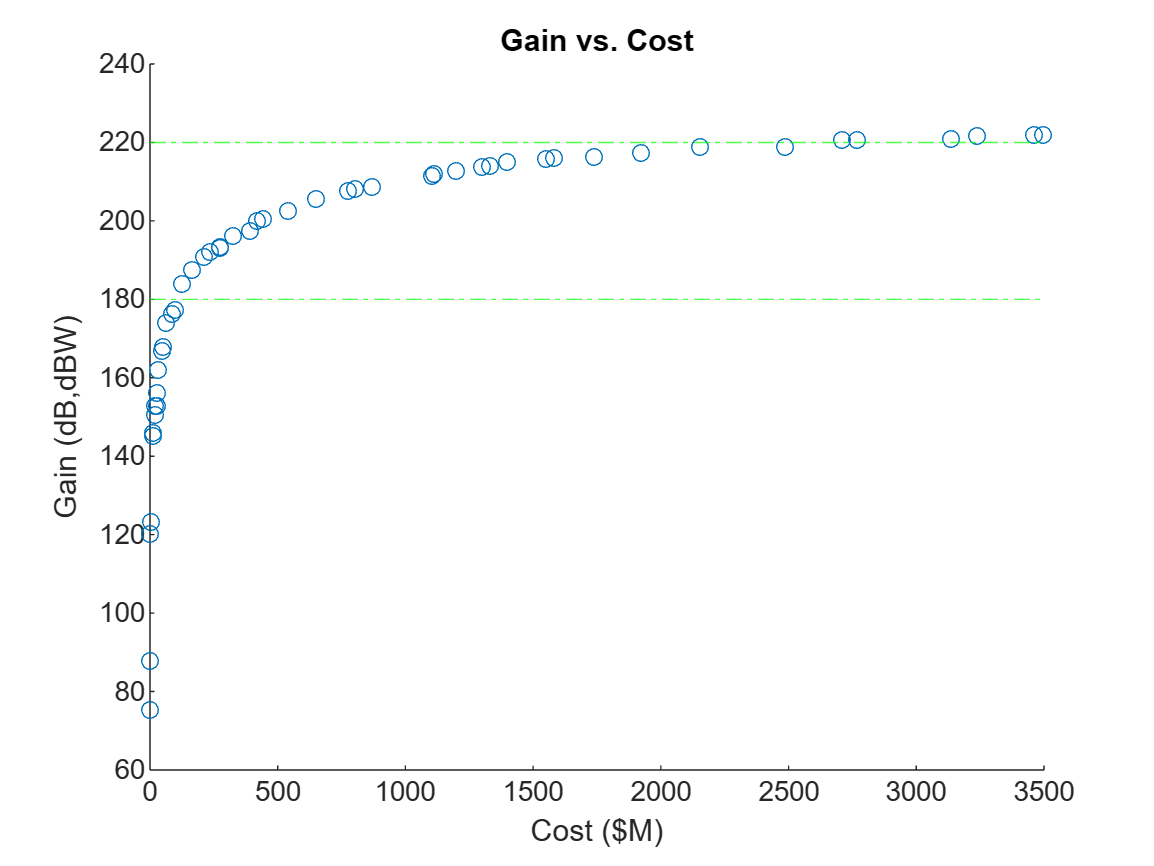

optimization_output(x,num_styles,operative_values, include_monostatic,loop_gain_desired, min_t_styles,min_r_styles,min_quantity,max_quantity,min_diameter,max_diameter,min_power,max_power,year_built,k,nu,max_antennas)